# 6.2 切比雪夫 I 型模拟低通：切比雪夫多项式、等纹波幅度平方函数、极点在椭圆上、与巴特沃思比阶数

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。设计公式自写（dsp_cheby1_analog 等），有工具箱时与 cheby1 对照。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
here = fileparts(mfilename('fullpath')); if endsWith(here, 'mlx'), here = fileparts(here); end
if ~exist(fullfile(here, 'dsp_freqz.m'), 'file'), here = fileparts(which('dsp_freqz')); end   % Live Script 里 mfilename 为空时靠路径找
codedir = here; addpath(codedir); outdir = fullfile(codedir, 'results'); if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：切比雪夫多项式 C_N(x)：递推 (6.1.11) 与闭式 (6.1.10) 一致；|x|≤1 内在 ±1 之间等幅振荡，x>1 后迅速增大

x = linspace(0, 3, 600);
C = zeros(5, numel(x)); C(1, :) = 1; C(2, :) = x;
for N = 2:4, C(N+1, :) = 2*x.*C(N, :) - C(N-1, :); end               % C_{N+1} = 2x C_N − C_{N−1}
Cclosed = @(N, x) (x <= 1).*cos(N*acos(min(x, 1))) + (x > 1).*cosh(N*acosh(max(x, 1)));
errC = 0; for N = 0:4, errC = max(errC, max(abs(C(N+1, :) - Cclosed(N, x)))); end

## 演示2：|Ha(jΩ)|² = 1/[1+ε²C_N²(Ω/Ωc)]，通带纹波 1 dB，N=1…6（教材式 (6.1.9)(6.1.13)、图 6.1.8）

ap = 1; eps = sqrt(10^(ap/10) - 1);                                    % 0.50885
W = linspace(0, 2, 2000); Wc = 1;
A2 = zeros(6, numel(W)); for N = 1:6, A2(N, :) = 1./(1 + eps^2*Cclosed(N, W/Wc).^2); end
A2at0 = A2(:, 1).';                                                     % N 奇为 1，N 偶为 1/(1+ε²)
A2atWc = 1./(1 + eps^2*Cclosed(1:6, 1).^2);                             % Ω=Ω_c：C_N(1)=1，恒为 1/(1+ε²)

## 演示3：极点在椭圆上（教材式 (6.1.18)—(6.1.22)、图 6.1.5）：例 6.8 的数值 N=4，ε=0.50885，Ωc=2tan(0.1π)=0.6498

Wc8 = 2*tan(0.1*pi);
[b4, a4, p4, aa, bb] = dsp_cheby1_analog(4, eps, Wc8);
beta = (sqrt(1 + 1/eps^2) + 1/eps)^(1/4);                              % 4.1702^(1/4)
pBook = [-0.0906699+0.6389997i, -0.0906699-0.6389997i, -0.2188969+0.2646819i, -0.2188969-0.2646819i];
errPoles = max(arrayfun(@(q) min(abs(p4 - q)), pBook));
secA = real(poly(p4([1 4]))); secB = real(poly(p4([2 3])));            % 共轭对配成二阶因子
[~, iA] = sort([secA(2) secB(2)]); secs = {secA, secB}; secs = secs(iA);   % 排成教材次序 (s²+0.1814s+0.4166)(s²+0.4378s+0.1180)?
Kbook = 0.04381; K4 = b4;
tt = linspace(0, 2*pi, 400); ell = aa*Wc8*cos(tt) + 1i*bb*Wc8*sin(tt);   % 极点所在椭圆
errSPT = NaN; if exist('cheby1', 'file') == 2, [~, aS] = cheby1(4, ap, Wc8, 's'); errSPT = max(abs(aS - a4)); end

## 演示4：同样指标（Ωp=0.2π 处 ≤1 dB，Ωs=0.3π 处 ≥15 dB）：巴特沃思要 6 阶，切比雪夫 4 阶（教材式 (6.1.15)）

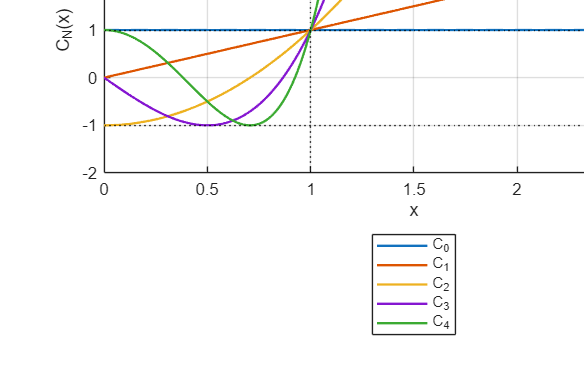

Wp = 0.2*pi; Ws = 0.3*pi; as = 15;
NcExact = acosh(sqrt(10^(as/10) - 1)/eps)/acosh(Ws/Wp); Nc = ceil(NcExact);
NbExact = log10((10^(as/10) - 1)/(10^(ap/10) - 1))/(2*log10(Ws/Wp)); Nb = ceil(NbExact);
[bc, ac] = dsp_cheby1_analog(Nc, eps, Wp);                             % 切比雪夫的 Ωc 就是通带边界
WcB = Wp/(10^(ap/10) - 1)^(1/(2*Nb)); [bbw, abw] = dsp_butter_analog(Nb, WcB);
attC = -20*log10(abs(dsp_freqs(bc, ac, [Wp Ws]))); attB = -20*log10(abs(dsp_freqs(bbw, abw, [Wp Ws])));
Wd = linspace(0, pi, 1024);

if ~LIVE, f1 = figure('Name','02 切比雪夫','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(x, C, 'LineWidth', 1.4); hold on; yline(1, 'k:'); yline(-1, 'k:'); xline(1, 'k:');
grid on; ylim([-2 4]); xlabel('x'); ylabel('C_N(x)');
title(sprintf('① 切比雪夫多项式 C_0…C_4：|x|≤1 时 |C_N|≤1，x>1 后按 cosh 增大（递推与闭式差 %.0e）', errC));
legend(compose('C_%d', 0:4));

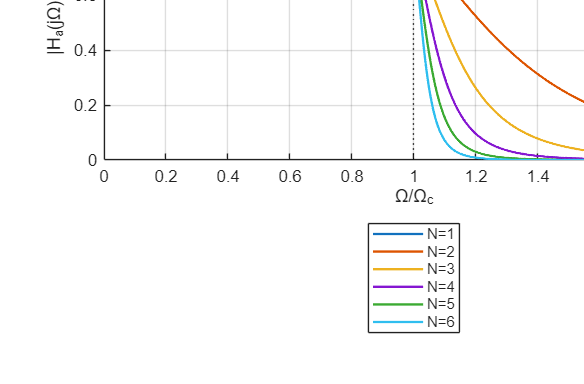

newpanel(); plot(W, A2, 'LineWidth', 1.4); hold on; yline(1/(1 + eps^2), 'k:', '1/(1+ε^2)'); xline(1, 'k:');
grid on; xlabel('Ω/Ω_c'); ylabel('|H_a(jΩ)|^2');
title(sprintf('② 1 dB 等纹波（ε=%.4f）：通带在 1 与 1/(1+ε²)=%.3f 之间振荡', eps, 1/(1+eps^2)));
legend(compose('N=%d', 1:6));

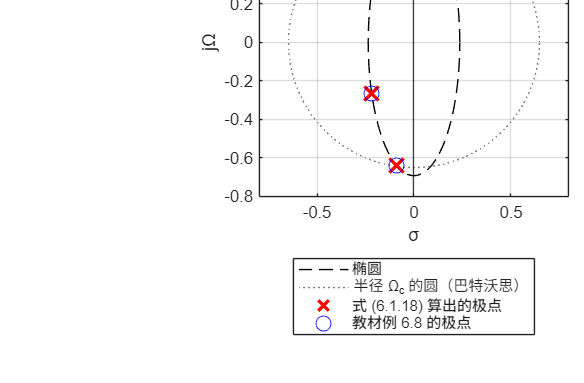

newpanel(); plot(real(ell), imag(ell), 'k--'); hold on; axis equal; grid on;
plot(Wc8*cos(tt), Wc8*sin(tt), ':', 'Color', [0.5 0.5 0.5]);
plot(real(p4), imag(p4), 'rx', 'MarkerSize', 12, 'LineWidth', 2); plot(real(pBook), imag(pBook), 'bo', 'MarkerSize', 9);
xline(0, 'k-'); xlim([-0.8 0.8]); ylim([-0.8 0.8]); xlabel('σ'); ylabel('jΩ');
title(sprintf('③ N=4、Ω_c=%.4f 的极点在椭圆上（半轴 %.4f、%.4f），与例 6.8 差 %.0e', Wc8, aa*Wc8, bb*Wc8, errPoles));
legend('椭圆', '半径 Ω_c 的圆（巴特沃思）', '式 (6.1.18) 算出的极点', '教材例 6.8 的极点');

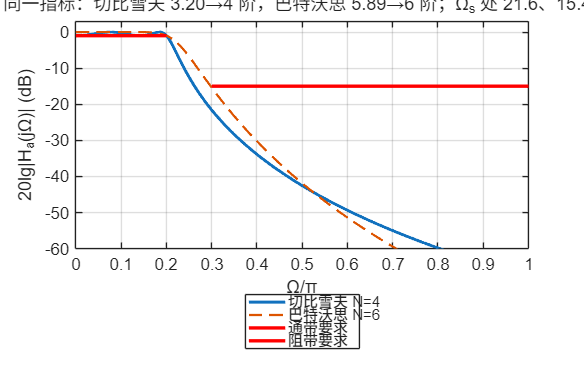

newpanel(); plot(Wd/pi, 20*log10(abs(dsp_freqs(bc, ac, Wd))), 'LineWidth', 1.8); hold on;
plot(Wd/pi, 20*log10(abs(dsp_freqs(bbw, abw, Wd))), '--', 'LineWidth', 1.4);
plot([0 Wp/pi], [-ap -ap], 'r-', 'LineWidth', 2); plot([Ws/pi 1], [-as -as], 'r-', 'LineWidth', 2);
grid on; ylim([-60 3]); xlabel('Ω/π'); ylabel('20lg|H_a(jΩ)| (dB)');
title(sprintf('④ 同一指标：切比雪夫 %.2f→%d 阶，巴特沃思 %.2f→%d 阶；Ω_s 处 %.1f、%.1f dB', NcExact, Nc, NbExact, Nb, attC(2), attB(2)));
legend(sprintf('切比雪夫 N=%d', Nc), sprintf('巴特沃思 N=%d', Nb), '通带要求', '阻带要求');

if ~LIVE, sgtitle('切比雪夫 I 型：通带等纹波换来更陡的过渡带；极点在椭圆上，参数 a、b 由 ε 和 N 决定'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '02-chebyshev.png'), 'Resolution', 150); end

## 教师核验

assert(errC < 1e-9, '递推与闭式不一致');
assert(abs(eps - 0.50885) < 1e-4, 'ε 与教材不符');
assert(all(abs(A2atWc - 1/(1 + eps^2)) < 1e-9), 'Ω=Ω_c 处应为 1/(1+ε²)');
assert(all(abs(A2at0(1:2:5) - 1) < 1e-9) && all(abs(A2at0(2:2:6) - 1/(1 + eps^2)) < 1e-9), 'Ω=0 处奇偶阶不同');
assert(abs(beta - 4.1702^(1/4)) < 1e-4 && abs(aa - 0.3646235) < 1e-4 && abs(bb - 1.0644015) < 1e-4, 'a、b 与例 6.8 不符');
assert(errPoles < 1e-4 && abs(K4 - Kbook) < 2e-5, '极点或增益与例 6.8 不符');   % 教材 a、b 只保留 7 位，极点差 4e-5
assert(Nc == 4 && Nb == 6 && attC(1) <= ap + 1e-9 && attC(2) >= as, '定阶或指标核验不符');
assert(isnan(errSPT) || errSPT < 1e-9, '与 cheby1 不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'eps_1dB', eps, 'A2_at_0_N1_6', A2at0, 'beta', beta, 'a', aa, 'b', bb, 'Wc_ex68', Wc8, 'poles_ex68_re', real(p4), 'poles_ex68_im', imag(p4), ...
    'gain_K', K4, 'section_A', secs{1}, 'section_B', secs{2}, 'err_poles_vs_book', errPoles, 'err_vs_cheby1', errSPT, ...
    'N_cheb_exact', NcExact, 'N_cheb', Nc, 'N_butter_exact', NbExact, 'N_butter', Nb, 'att_cheb_wp_ws', attC, 'att_butter_wp_ws', attB, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-chebyshev.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 21:31:17'
              eps_1dB: 0.5088
         A2_at_0_N1_6: [1 0.7943 1 0.7943 1 0.7943]
                 beta: 1.4290
                    a: 0.3646
                    b: 1.0644
              Wc_ex68: 0.6498
        poles_ex68_re: [-0.0907 -0.2189 -0.2189 -0.0907]
        poles_ex68_im: [0.6390 0.2647 -0.2647 -0.6390]
               gain_K: 0.0438
            section_A: [1 0.1814 0.4166]
            section_B: [1 0.4378 0.1180]
    err_poles_vs_book: 3.9293e-05
        err_vs_cheby1: 3.3307e-16
         N_cheb_exact: 3.1977
               N_cheb: 4
       N_butter_exact: 5.8858
             N_butter: 6
       att_cheb_wp_ws: [1.0000 21.5834]
     att_butter_wp_ws: [1.0000 15.3901]
    all_checks_passed: 1


课堂图已保存到：G:\2026-Agent\数字信号处理\课程网站\ch6\code\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end